# SISTEMES d'EQUACIONS (SESSIÓ 8)

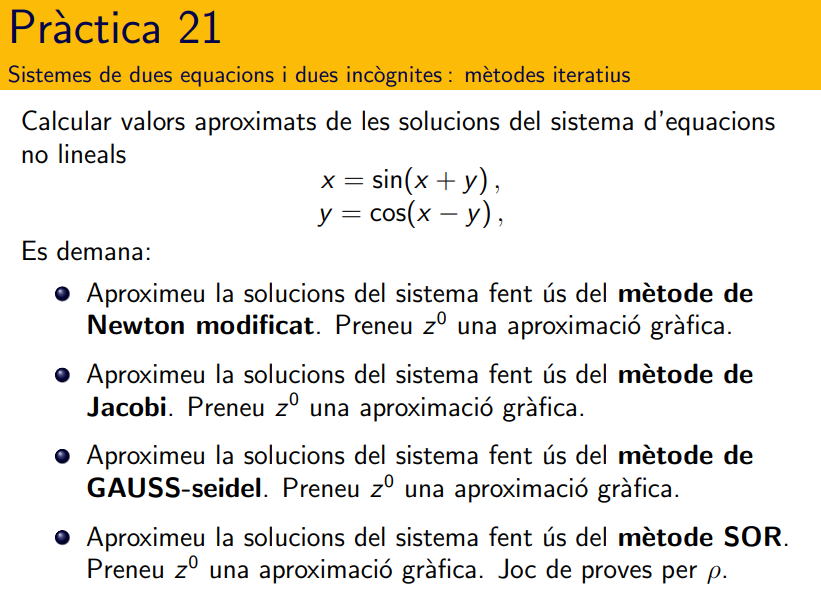

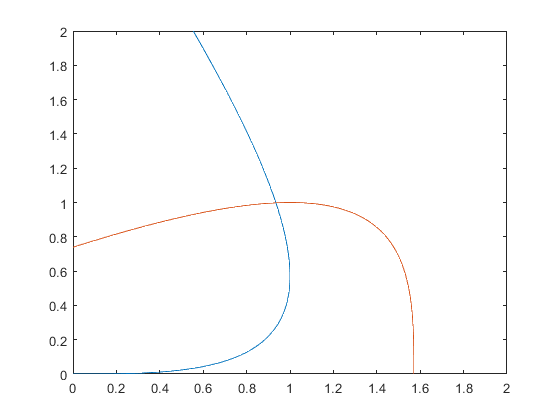

clearvars; format short g;

F1=@(x,y)x-sin(x+y);
F2=@(x,y)y-cos(x-y);
fimplicit({F1,F2}); xlim([0 2]); ylim([0 2]);

Podemos ver como aproximadamente la solucion se encuentra cerca del punto (0.9, 1.0). Tomamos z0 = (0.9, 1.0):

Z0=[1;0.9];

F=@(x,y)[x-sin(x+y); y-cos(x-y)]; F(Z0(1),Z0(2));
DF=@(x,y)[1-cos(x+y), -cos(x+y); sin(x-y), 1-sin(x-y)];

tolZ=0.5*10^(-7);
tolF= 0.5*10^(-7); 
Nmax=1000;

## Netwon Modificado

fixed_it = 5;   % Numero fijo de iteraciones en el que se mantiene la matriz de iteracion sin cambiar.
tic; alpha = newton2dMOD(F,DF,Z0,Nmax,tolF,tolZ,fixed_it); toc;


solución = 0.93508     0.99802
tolF = 3.1673e-14
tolZ = 7.1154e-10
iteraciones = 7

Elapsed time is 0.001945 seconds.


## Metodo de Jacobi

tic; alpha = newton2dJACOBI(F,DF,Z0,Nmax,tolF,tolZ); toc;


solución = 0.93508     0.99802
tolF = 1.7596e-09
tolZ = 7.2359e-09
iteraciones = 9

Elapsed time is 0.002693 seconds.


## Metodo de Gauss-Seidel

tic; alpha = newton2dGS(F,DF,Z0,Nmax,tolF,tolZ); toc;


solución = 0.93508     0.99802
tolF = 4.3957e-10
tolZ = 2.0982e-08
iteraciones = 6

Elapsed time is 0.000747 seconds.


## Metodo de SOR

for w = 0.1:0.1:1.9 % 0 < w < 2
    rho = 1/w - 1;
    tic; alpha = newton2dSOR(F,DF,Z0,Nmax,tolF,tolZ,rho); toc;
end


solución = 0.93508     0.99802
RHO = 9
tolF = 4.9936e-08
tolZ = 4.1793e-09
iteraciones = 147

Elapsed time is 0.001074 seconds.

solución = 0.93508     0.99802
RHO = 4
tolF = 4.5037e-08
tolZ = 8.547e-09
iteraciones = 70

Elapsed time is 0.000638 seconds.

solución = 0.93508     0.99802
RHO = 2.3333
tolF = 4.3218e-08
tolZ = 1.4187e-08
iteraciones = 44

Elapsed time is 0.000716 seconds.

solución = 0.93508     0.99802
RHO = 1.5
tolF = 3.8445e-08
tolZ = 1.9884e-08
iteraciones = 31

Elapsed time is 0.000888 seconds.

solución = 0.93508     0.99802
RHO = 1
tolF = 3.52e-08
tolZ = 2.7795e-08
iteraciones = 23

Elapsed time is 0.000788 seconds.

solución = 0.93508     0.99802
RHO = 0.66667
tolF = 1.9239e-08
tolZ = 2.3733e-08
iteraciones = 18

Elapsed time is 0.000429 seconds.

solución = 0.93508     0.99802
RHO = 0.42857
tolF = 1.1642e-08
tolZ = 2.4117e-08
iteraciones = 14

Elapsed time is 0.000411 seconds.

solución = 0.93508     0.99802
RHO = 0.25
tolF = 2.0954e-09
tolZ = 1.0927e-08
iteracio